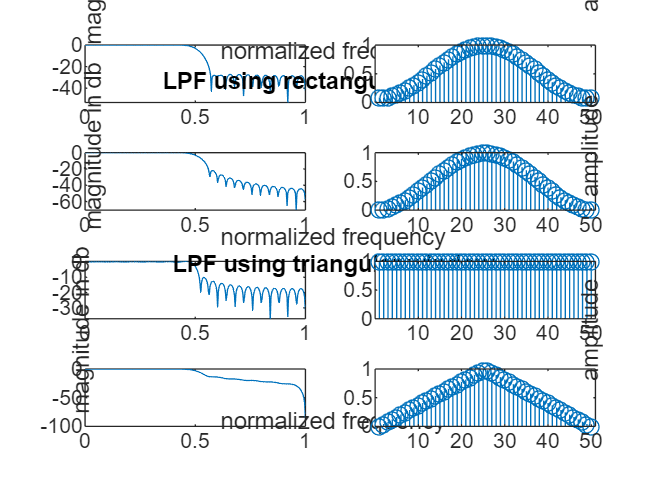

clc;
clear all;
close all;
wc = 0.5*pi;
N=50;
alpha = (N-1)/2;
n=0:1:N-1;
hd=sin(wc*(n-alpha))./(pi*(n-alpha));
%LPFhamming
w1=hamming(N);
hn=hd.*w1';
w=0:0.01:pi;
h1=freqz(hn,1,w);
subplot(4,2,1);
plot(w/pi,10*log10(abs(h1)));
title('LPF using hamming window');
xlabel('normalized frequency');
ylabel('magnitude in db');
%LPFhanning
w2=hanning(N);
hn=hd.*w2';
w=0:0.01:pi;
h2=freqz(hn,1,w);
subplot(4,2,3);
plot(w/pi,10*log10(abs(h2)));
title('LPF using hanning window');
xlabel('normalized frequency');
ylabel('magnitude in db');
%LPFrect
w3=boxcar(N);
hn=hd.*w3';
w=0:0.01:pi;
h3=freqz(hn,1,w);
subplot(4,2,5);
plot(w/pi,10*log10(abs(h3)));
title('LPF using rectangular window');
xlabel('normalized frequency');
ylabel('magnitude in db');
%LPFtri
w4=bartlett(N);
hn=hd.*w4';
w=0:0.01:pi;
h4=freqz(hn,1,w);
subplot(4,2,7);
plot(w/pi,10*log10(abs(h4)));
title('LPF using triangular window');
xlabel('normalized frequency');
ylabel('magnitude in db');

%hamming
subplot(4,2,2);
stem(w1);
title('hamming window sequence');
xlabel('no of samples');
ylabel('amplitude');
%hanning
subplot(4,2,4);
stem(w2);
title('hanning window sequence');
xlabel('no of samples');
ylabel('amplitude');
%rectangular
subplot(4,2,6);
stem(w3);
title('rectangular window sequence');
xlabel('no of samples');
ylabel('amplitude');
%triangular
subplot(4,2,8);
stem(w4);
title('tirangular window sequence');
xlabel('no of samples');
ylabel('amplitude');